% judp.m--Uses Matlab's Java interface to handle User Datagram Protocol
% (UDP) communications with another application, either on the same
% computer or a remote one. 
%
% JUDP('SEND',PORT,HOST,MSSG) sends a message to the specifed port and
% host. HOST can be either a hostname (e.g., 'www.example.com') or a string
% representation of an IP address (e.g., '192.0.34.166'). PORT, the port
% number on the target machine, is an integer port number between 1025 and
% 65535. The specified port must be open in the receiving machine's
% firewall. If PORT is a 2-element vector of integers, rather than a single
% integer, the first element represents the target (receiving) port number
% as before, while the second element represents the local (source) port.
% 
% MSSG = JUDP('RECEIVE',PORT,PACKETLENGTH) receives a message over the
% specified port. PACKETLENGTH should be set to the maximum expected
% message length to be received in the UDP packet; if too small, the
% message will be truncated.
%
% MSSG = JUDP('RECEIVE',PORT,PACKETLENGTH,TIMEOUT) attempts to receive a
% message but times out after TIMEOUT milliseconds. If TIMEOUT is not
% specified, as in the previous example, a default value is used.
%
% [MSSG,SOURCEHOST] = JUDP('RECEIVE',...) returns a string representation
% of the originating host's IP address, in addition to the received
% message. 
%
% Messages sent by judp.m are in int8 format. The int8.m function can be
% used to convert integers or characters to the correct format (use
% double.m or char.m to convert back after the datagram is received). 
% Non-integer values can be converted to int8 format using typecast.m (use
% typecast.m to convert back).
% 
% e.g.,   mssg = judp('receive',21566,10); char(mssg')
%         judp('send',21566,'208.77.188.166',int8('Howdy!'))         
%
% e.g.,   [mssg,sourceHost] = judp('receive',21566,10,5000)
%         judp('send',21566,'www.example.com',int8([1 2 3 4]))
%         
% e.g.,   mssg = judp('receive',21566,200); typecast(mssg,'double')
%         judp('send',21566,'localhost',typecast([1.1 2.2 3.3],'int8'))
% Developed in Matlab 7.8.0.347 (R2009a) on GLNX86.
% Kevin Bartlett (kpb@uvic.ca), 2009-06-18 16:11
%-------------------------------------------------------------------------
%-------------------------------------------------------------------------
% REVISION HISTORY
% 
% 2021-07-05: At suggestion of Dennie Craane, added ability to specify both
% a source port number and a target port number when sending packets.
%-------------------------------------------------------------------------

MSSG = judp('RECEIVE', 8080, 1400)

MSSG = 1400×1 int8 column vector
   -10
    37
     0
     0
     0
     0
     0
     0
     0
     0


X = int16(MSSG);
for i= 1:1400
    if (X(i) < 0)
        X(i) = X(i) + 255;
    else
        X(i) = X(i);
    end
end
X0 = X(1:700);
X1 = X(701:1400);
y = X1 * 255 + X0;
t = 0:0.01:7-0.01;
u = floor((0:699)/5);
save('servo5.mat','t','u','y');


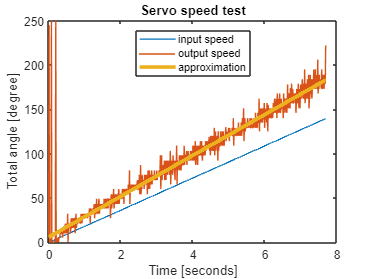

load("servo3.mat");
t = 0:0.011:7.7-0.011;
u_hat = u*1.27+6;
plot(t,u,'LineWidth',1)
hold on
plot(t,y)
plot(t,u_hat, 'LineWidth',3)
hold off
title('Servo speed test');
legend('input speed', 'output speed', 'approximation','Location','north');
xlabel('Time [seconds]');
ylabel('Total angle [degree]');

load("servo2.mat");
t = 0:0.1:70-0.1;
u = floor((0:699)/5);
u_hat = u*1.3+6;
plot(t,u,'LineWidth',1)
hold on
plot(t,y)
plot(t,u_hat, 'LineWidth',3)
hold off

load("servo.mat");
t = 0:0.101:70.7-0.101;
u = floor((0:699)/70) * 14;
u_hat = u*1.3+6
plot(t,u,'LineWidth',1)
hold on
plot(t,y)
plot(t,u_hat, 'LineWidth',3)
hold off


% The easiest way to establish the open loop controler:
% 1. Take a range of instantaneous angular speed within [10,140]
% 2. Implement the stimulus signal as a reversed formula: u_hat = u*1.3 + 6
% Another words, feed it u = (u_hat - 6) / 1.3
% !!! but:
% 1. It's needed to check that this is a proper turn for all servos, not
% only for that one I have here.
% 2. Also it's totally not the fact that servo under load will provide the same characterristic.
% Ideally, we need an after-launch algorithm for self calibration.
% !!!

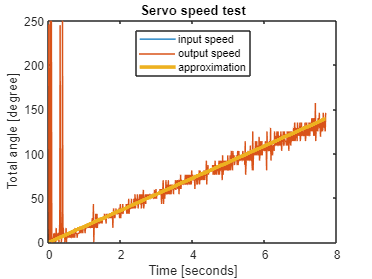

load("servo4.mat");
t = 0:0.011:7.7-0.011;
u_hat = u;
plot(t,u,'LineWidth',1)
hold on
plot(t,y)
plot(t,u_hat, 'LineWidth',3)
hold off
title('Servo speed test');
legend('input speed', 'output speed', 'approximation','Location','north');
xlabel('Time [seconds]');
ylabel('Total angle [degree]');

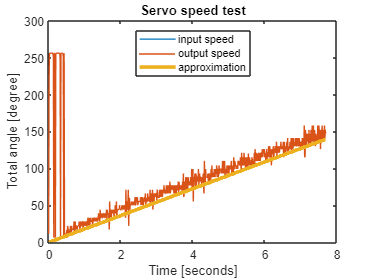

load("servo5.mat");
t = 0:0.011:7.7-0.011;
u_hat = u;
plot(t,u,'LineWidth',1)
hold on
plot(t,256-y)
plot(t,u_hat, 'LineWidth',3)
hold off
title('Servo speed test');
legend('input speed', 'output speed', 'approximation','Location','north');
xlabel('Time [seconds]');
ylabel('Total angle [degree]');


% this is a backverse rotation.